if ~exist('Option','var')
    disp("Option struct does not exist, creating one")
    addpath(genpath(codedefine()));
    Option = option.defaults(); 
else
    disp("Option struct already exists, using that")
    Option = option.setdefaults(Option);
    disp("Option struct is: ")
    disp(Option)
end

Option struct already exists, using that


Default = 包含以下字段的 struct :
                           animal: "ZT2"
                     samplingRate: []
                     spikeBinSize: 0.0500
                          winSize: [0 0.3000]
          positiveDerivativeCheck: [0 0.1500]
       equalWindowsAcrossPatterns: 1
            quantileToMakeWindows: 0.8500
       thetadelta_outlierQuantile: [0 0.9950]
                   spikeShiftSize: 0.0100
                    timesPerTrial: 30
                       sourceArea: "CA1"
                 waysOfPartitions: 2
                    singleControl: 0
               oldControlBehavior: 0
                     lowerControl: 1
                    binsToMatchFR: 20
           preProcess_FilterLowFR: 1
    preProcess_matchingDiscreteFR: 1
        preProcess_gaussianFilter: 5
                preProcess_zscore: 1
                     numPartition: 50
                  dimCompAnalysis: 5
                       stablePerf: 0.9000
                        generateH: "fromSpectra  fromRipTimes"


Option struct is: 


                           animal: "ER1"
                     samplingRate: []
                     spikeBinSize: 0.0250
                          winSize: [-0.5000 0.5000]
          positiveDerivativeCheck: [0 0.1500]
       equalWindowsAcrossPatterns: 1
            quantileToMakeWindows: 0.8500
       thetadelta_outlierQuantile: [0 0.9950]
                   spikeShiftSize: 0.0100
                    timesPerTrial: 60
                       sourceArea: "CA1"
                 waysOfPartitions: 2
                    singleControl: 0
               oldControlBehavior: 0
                     lowerControl: 1
                    binsToMatchFR: 20
           preProcess_FilterLowFR: 1
    preProcess_matchingDiscreteFR: 1
        preProcess_gaussianFilter: 5
                preProcess_zscore: 0
                     numPartition: 40
                  dimCompAnalysis: 5
                       stablePerf: 0.9000
                        generateH: "fromSpectra  fromRipTimes"
                     


% Windowing parameters
Option.spikeBinSize = 0.025;
Option.timesPerTrial = 60;
Option.winSize = [-0.5 0.5];
Option.preProcess_zscore = false;
Option.numPartition = 40;
Option.animal = "JS15";
Option

Option = 包含以下字段的 struct :
                           animal: "JS15"
                     samplingRate: []
                     spikeBinSize: 0.0250
                          winSize: [-0.5000 0.5000]
          positiveDerivativeCheck: [0 0.1500]
       equalWindowsAcrossPatterns: 1
            quantileToMakeWindows: 0.8500
       thetadelta_outlierQuantile: [0 0.9950]
                   spikeShiftSize: 0.0100
                    timesPerTrial: 60
                       sourceArea: "CA1"
                 waysOfPartitions: 2
                    singleControl: 0
               oldControlBehavior: 0
                     lowerControl: 1
                    binsToMatchFR: 20
           preProcess_FilterLowFR: 1
    preProcess_matchingDiscreteFR: 1
        preProcess_gaussianFilter: 5
                preProcess_zscore: 0
                     numPartition: 40
                  dimCompAnalysis: 5
                       stablePerf: 0.9000
                        generateH: "fromSpectra  fromRipT


%%%%%%%%%%%%%%%% DISPLAY OUR OPTIONS TO USER %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%{
if isequal(Option.loadifexists, false) && ...
    exist(store.gethash(Option) + ".mat", 'file')
    disp("Loading from file: " + store.gethash(Option) + ".mat")
    m = matfile(store.gethash(Option) + ".mat");
    % m = matfile("bef0923.mat", "Writable", true);
    disp("Loaded variables: ")
    Events             = util.matfile.getdefault(m, 'Events', []);
    Spk                = util.matfile.getdefault(m, 'Spk', []);
    Patterns           = util.matfile.getdefault(m, 'Patterns', []);
    Patterns_overall   = util.matfile.getdefault(m, 'Patterns_overall', []);
    Components         = util.matfile.getdefault(m, 'Components', []);
    Components_overall = util.matfile.getdefault(m, 'Components_overall', []);
    Option             = util.matfile.getdefault(m, 'Option', []);
    disp("...done")
else
%}
    %%%%%%%%%%%%%%%% OBTAIN EVENT MATRICES    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Getting behavior
    [behavior, thrown_out_times] = table.behavior.lookup(Option.animal, ...
                                                         []);

Starting lookup for JS1	Table with fields: time, vel, lindist, tperf_timewise, region, traj, trajbound, rewarded, X, Y, day, epoch

Converting to table:  000%  |                                          | 0/16 [00:00:00<Inf:NaN:NaN, Inf it/s]Throwing out times greater than 2 seconds away
Done with addToBehavior ... took 9.8231 seconds


    Events = events.initEvents();
    % Test case 1: TriggerOn when velocity (vel) exceeds a certain threshold
    Events = events.generateFromBehavior(behavior, {'rewardTimes'}, ...
        Events, 'triggerOnValues', {1}, ...
                'triggerOnVarnames', {'rewardTimes'}, ...
                'windowParameters',Option.winSize);

Triggering on rewardTimes = 1


    Events = events.generateFromBehavior(behavior, {'rewardTimes'}, ...
        Events, 'triggerOffValues', {1}, ...
                'triggerOffVarnames', {'rewardTimes'}, ...
                'windowParameters',Option.winSize);

Triggering off rewardTimes = 1


    qselect = @(x) (x.idphi > quantile(x.idphi, 0.95)) & (abs(x.vel) > 3);
    Events = events.generateFromBehavior(behavior, {'idphi'}, ...
        Events, 'triggerVarLambdas', {qselect}, ...
                'triggerVars', {'idphi'}, ...
                'maxWindows', 2000, ...
                'windowParameters',Option.winSize);

Triggering on idphi


    qselect2 = @(x) (x.idphi < quantile(x.idphi, 0.05)) & (abs(x.vel) > 3);
    Events = events.generateFromBehavior(behavior, {'idphi'}, ...
        Events, 'triggerVarLambdas', {qselect2}, ...
                'triggerVars', {'idphi'}, ...
                'maxWindows', 2000, ...
                'windowParameters',Option.winSize);

Triggering on idphi


    % Characterize events
    %figure; events.plot_events(Events, 'rewardTimes');
    % figure; events.plotIEI(Events, 'NumBins', 1000);
    %figure; events.plotCrossIEI(Events, 'NumBins', 1000, 'layout', 'matrix');
    Option.nPatternAndControl = numel(Events.cellOfWindows);
    Option.patternNames = ["rewardOn", "rewardOff","idphi","idphi_low"];



quantile(behavior.idphi, 0.2)

ans = 0.1046


    %%%%%%%%%%%%%%%% ACQUIRE SPIKES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Getting spikes
    disp("------------------------")

------------------------


    disp("    Getting spikes      ")

    Getting spikes      


    disp("------------------------")

------------------------


    Spk = spikes.getSpikeTrain(Option.animal, Option.spikeBinSize, ...
                               Option.samplingRate);

...loading spikes for ZT2
...finding start and end times of the day
...done 38.4655 seconds


    % filter the neurons whose firing rate is lower than specified threshold
    if Option.preProcess_FilterLowFR 
        disp("------------------------")
        disp("Filtering low FR neurons")
        disp("------------------------")
        Spk = trialSpikes.filterFR(Spk, 0.1);
        disp("Mean FR: " + sort(Spk.avgFR))
    end

------------------------


Filtering low FR neurons


------------------------


    "Mean FR: 0.111289"
    "Mean FR: 0.114746"
    "Mean FR: 0.116194"
    "Mean FR: 0.116951"
    "Mean FR: 0.120111"
    "Mean FR: 0.120473"
    "Mean FR: 0.120703"
    "Mean FR: 0.120967"
    "Mean FR: 0.124357"
    "Mean FR: 0.127023"
    "Mean FR: 0.131763"
    "Mean FR: 0.132125"
    "Mean FR: 0.133277"
    "Mean FR: 0.135318"
    "Mean FR: 0.136832"
    "Mean FR: 0.14019"
    "Mean FR: 0.141473"
    "Mean FR: 0.147596"
    "Mean FR: 0.156845"
    "Mean FR: 0.157833"
    "Mean FR: 0.170077"
    "Mean FR: 0.172809"
    "Mean FR: 0.175904"
    "Mean FR: 0.188543"
    "Mean FR: 0.192296"
    "Mean FR: 0.196147"
    "Mean FR: 0.197233"
    "Mean FR: 0.200525"
    "Mean FR: 0.203619"
    "Mean FR: 0.205331"
    "Mean FR: 0.208359"
    "Mean FR: 0.211157"
    "Mean FR: 0.211486"
    "Mean FR: 0.213955"
    "Mean FR: 0.214053"
    "Mean FR: 0.214152"
    "Mean FR: 0.21876"
    "Mean FR: 0.228372"
    "Mean FR: 0.228701"
    "Mean FR: 0.238905"
    "Mean FR: 0.239596"
    "Mean FR: 0.25

    if Option.preProcess_gaussianFilter
        % Gaussian filter the spikeCountMatrix/spikeRateMatrix
        gauss = gausswin(Option.preProcess_gaussianFilter);
        for i = progress(1:size(Spk.spikeRateMatrix, 1), 'Title', 'Gaussian filtering')
            Spk.spikeRateMatrix(i, :)  = conv(Spk.spikeRateMatrix(i, :), gauss, 'same');
            Spk.spikeCountMatrix(i, :) = conv(Spk.spikeCountMatrix(i, :), gauss, 'same');
        end
    end

Gaussian filtering:  000%  |                                        | 0/224 [00:00:00<Inf:NaN:NaN, Inf it/s]


    if Option.preProcess_zscore
        % Z-score the spikeCountMatrix/spikeRateMatrix
        disp(" Z-scoring ")
        if ~isfield(Spk, 'muFR')
            Spk.muFR  = mean(Spk.spikeRateMatrix, 2);
            Spk.stdFR = std(Spk.spikeRateMatrix, 0, 2);
        end
        Spk.spikeRateMatrix  = zscore(Spk.spikeRateMatrix,  0, 2);
        Spk.spikeCountMatrix = zscore(Spk.spikeCountMatrix, 0, 2);
        Spk.avgFR = mean(Spk.spikeRateMatrix, 2);
    end
    prewindow_copy = Spk;


    % %%%%%%%%%%%%%% ACQUIRE TRIALS FROM WINDOWS + SPIKES %%%%%%%%%%%%%%%%%%%
    % RYAN bug here .. timeBinStartEnd instead of timeBinMidPoints
    disp("------------------------")

------------------------


    disp("   Windowing spikes     ")

   Windowing spikes     


    disp("------------------------")

------------------------


    Spk = trialSpikes.generate(Spk, Events, Option);

Generating spike sample matrix and tensor

Patterns:  000%  |                                            | 0/4 [00:00:00<Inf:NaN:NaN, Inf it/s]Checking for rank deficiency
Rank deficient ... solving ...
Solving rank deficient matrix....
Solved rank deficient matrix in 20.0667 seconds.
Checking for rank deficiency
Rank deficient ... solving ...
Solving rank deficient matrix....
Solved rank deficient matrix in 19.0946 seconds.'pushover-cli' 不是内部或外部命令，也不是可运行的程序 
或批处理文件。 
Checking for rank deficiency
Rank deficient ... solving ...
Solving rank deficient matrix....
Solved rank deficient matrix in 93.8739 seconds.'pushover-cli' 不是内部或外部命令，也不是可运行的程序 
或批处理文件。 
Checking for rank deficiency
Rank deficient'pushover-cli' 不是内部或外部命令，也不是可运行的程序 
或批处理文件。 



    %%%%%%%%%%%%%%%%% SETUP RAW DATA STRUCTURE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Structure for separated data
    %%%%%%%%%%%%%%%% SEPRATE BRAIN AREA DATASULT STRUCTURES %%%%%%%%%%%%%%%%%%
    % Separate spikesSampleMatrix/Tensor by area that neurons are in PFC and
    % neurons that in HPC
     
    %% Separate firing pattern into source and target
    [Spk.nSource,~,~] = size(Spk.hpc.X{1});
    [Spk.nTarget,~,~] = size(Spk.pfc.X{1});
    Spk.celllookup = cellInfo.getCellIdentities(Option.animal, Spk.cell_index,...
                                                Spk.areaPerNeuron);

L

    system("pushover-cli 'Finished munging data for analysis'");

'pushover-cli' 不是内部或外部命令，也不是可运行的程序 
或批处理文件。 



    %%%%%%%%%%%%%%%% SETUP PARTITIONS AND RESULT STRUCTURES %%%%%%%%%%%%%%%%%%
    disp("------------------------")

------------------------


    disp(" Subsampling partitions ")

 Subsampling partitions 


    disp("------------------------")

------------------------


    Option.numPartition = 40;
    [Patterns, Patterns_overall] = trialSpikes.partitionAndInitialize(Spk, Option);

Partitioning data...

'pushover-cli' 不是内部或外部命令，也不是可运行的程序 
或批处理文件。 
Partitioning data took 106.9276 seconds.


    Components = nd.initFrom(Patterns, ...
    {'index_source', 'index_target', 'directionality', 'name'});
    Components_overall = nd.initFrom(Patterns_overall, ...
    {'index_source', 'index_target', 'directionality', 'name'});



Running CCA analysis...


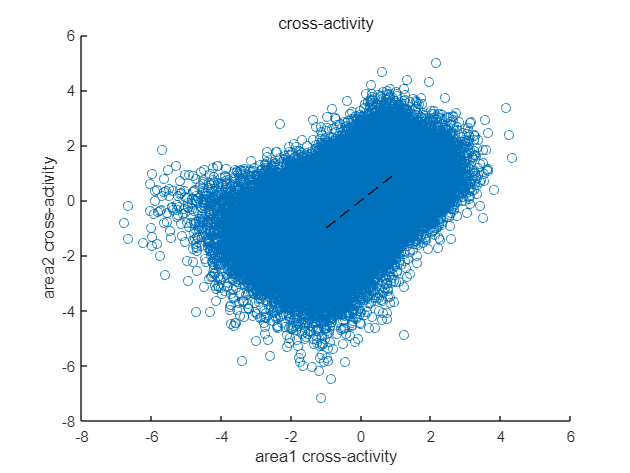

CCA analysis completed in 11.2959 s


Patterns_overall_cca = analysis.cca(Patterns_overall(2,5), Option);

% 假设您已经有了idphi向量、时间向量、u向量和v向量
idphi_vector = behavior.idphi; % 231754长度的IdPhi向量
time_idphi = behavior.time;   % 对应IdPhi向量的时间向量
time_u_v = Patterns_overall_cca.X_time;     % 330772长度的u和v的时间向量
u_vector = Patterns_overall_cca.cca.u(:,1);     % 对应时间点的u向量
v_vector = Patterns_overall_cca.cca.v(:,1);     % 对应时间点的v向量

% 创建一个用于存储匹配的IdPhi数据的向量和对应的时间向量
matched_u = [];
matched_v = [];

% 将IdPhi的时间对应到u和v的时间点上
for i = 1:length(idphi_vector)
    disp(i)
    [~, idx] = min(abs(time_idphi - time_u_v(i)));
    
    if time_idphi(idx) == time_u_v(i)
        matched_u(i) = u_vector(idx);
        matched_v(i) = v_vector(idx);
    else
        % 如果找不到精确匹配的时间，进行插值
        matched_u(i) = interp1(time_u_v, u_vector, time_idphi(i), 'linear', 'extrap');
        matched_v(i) = interp1(time_u_v, v_vector, time_idphi(i), 'linear', 'extrap');
    end
end

idphi_vector =     0.9480
    0.9480
    0.9480
    1.0228
    1.0976
    1.0976
    1.1724
    1.2999
    1.5022
    1.5887


time_idphi = 1.0e+04 *

    0.2001
    0.2001
    0.2001
    0.2001
    0.2001
    0.2001
    0.2001
    0.2001
    0.2001
    0.2001


time_u_v = 1.0e+04 *

    0.2001    0.2001    0.2001    0.2001    0.2001    0.2001    0.2001    0.2001    0.2001    0.2001    0.2001    0.2001    0.2001    0.2001    0.2001    0.2001    0.2001    0.2001    0.2001    0.2001    0.2001    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002


u_vector =     0.2153
    0.1613
   -0.1386
   -0.2142
   -0.2193
   -0.2990
    0.0424
    0.4816
    0.3433
    0.2578


v_vector =     0.7610
    1.1164
    0.4051
    0.2217
   -0.3633
   -0.1430
    0.7984
    0.9985
    0.2564
    0.3133


idphi_vector = idphi_vector(find(abs(behavior.vel) > 3));

matched_u = matched_u(find(abs(behavior.vel) > 3));
matched_v = matched_v(find(abs(behavior.vel) > 3));

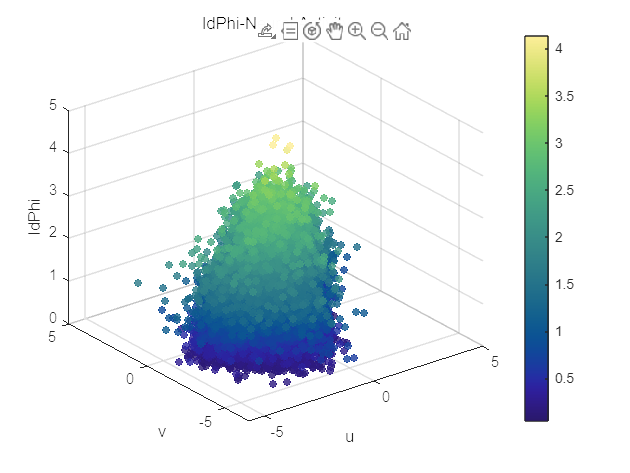


% 假设 A、B、C 分别是你的向量
A = matched_u; % 示例随机数据
B = matched_v; % 示例随机数据
C = idphi_vector; % 示例随机数据

% 使用 scatter3 创建散点图
figure;
scatter3(A, B, C, 20, C, 'filled',"MarkerEdgeColor","flat","MarkerFaceAlpha",0.8);
colormap(cmocean('haline')); % 设置颜色映射为 cmocean 的 'haline' 映射
colorbar; % 添加颜色条
xlabel('u','FontSize',4);
ylabel('v', 'FontSize',4);
zlabel('IdPhi','FontSize',4);
title('IdPhi-Neural Activity', FontSize=5);

saveas(gcf,"F:/ComSub/Figures/idphi and reward/IdPhi-Neural Activity.png")

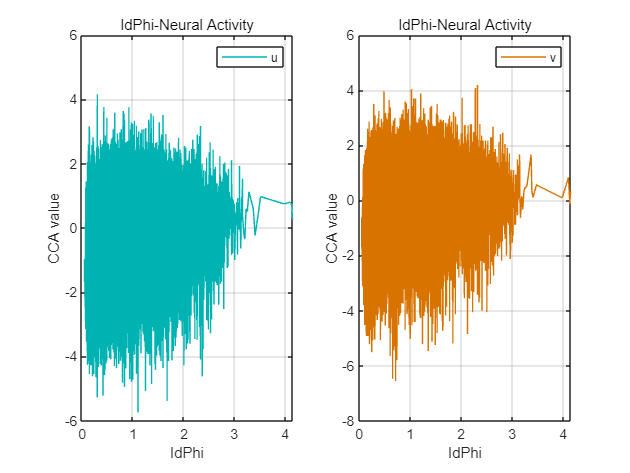

% 对 C 向量进行排序，同时重新排列 A 和 B 向量的元素
[C_sorted, sort_indices] = sort(C, 'descend');
A_sorted = A(sort_indices);
B_sorted = B(sort_indices);

figure;

% 调整子图的位置和大小
subplot(1, 2, 1); % [left, bottom, width, height]
plot(C_sorted, A_sorted, 'color', [0, 0.7, 0.7], 'LineWidth', 0.5);
xlabel('IdPhi');
ylabel('CCA value');
title('IdPhi-Neural Activity');
grid on;
legend('u');

subplot(1, 2, 2);
plot(C_sorted, B_sorted, 'color', [0.85, 0.45, 0], 'LineWidth', 0.5);
xlabel('IdPhi');
ylabel('CCA value');
title('IdPhi-Neural Activity');
grid on;
legend('v');
saveas(gcf,"F:/ComSub/Figures/idphi and reward/IdPhi-Neural Activity2D.png")

% 假设您已经有了idphi向量、时间向量、u向量和v向量
lindist = behavior.lindist; % 231754长度的IdPhi向量
idphi_vector = behavior.idphi; % 231754长度的IdPhi向量
time = behavior.time;   % 对应IdPhi向量的时间向量
time_u_v = Patterns_overall_cca.X_time;     % 330772长度的u和v的时间向量
u_vector = Patterns_overall_cca.cca.u(:,1);     % 对应时间点的u向量
v_vector = Patterns_overall_cca.cca.v(:,1);     % 对应时间点的v向量

% 创建一个用于存储匹配的IdPhi数据的向量和对应的时间向量
matched_u = [];
matched_v = [];

% 将IdPhi的时间对应到u和v的时间点上
for i = 1:length(time)
    disp(i)
    [~, idx] = min(abs(time - time_u_v(i)));
    
    if time(idx) == time_u_v(i)
        matched_u(i) = u_vector(idx);
        matched_v(i) = v_vector(idx);
    else
        % 如果找不到精确匹配的时间，进行插值
        matched_u(i) = interp1(time_u_v, u_vector, time(i), 'linear', 'extrap');
        matched_v(i) = interp1(time_u_v, v_vector, time(i), 'linear', 'extrap');
    end
end

% Filter indices based on velocity conditions
idx = find(abs(behavior.vel) > 5 & behavior.trajbound == 1);
idx2 = find(abs(behavior.vel) > 3 & behavior.trajbound == 1);
idx3 = find(abs(behavior.vel) > 5 & behavior.trajbound == 0);
idx4 = find(abs(behavior.vel) > 3 & behavior.trajbound == 0);

% Apply index filtering to matched_u and matched_v arrays
matched_u1_filtered = matched_u(idx);
matched_v1_filtered = matched_v(idx);
matched_u2_filtered = matched_u(idx2);
matched_v2_filtered = matched_v(idx2);
matched_u3_filtered = matched_u(idx3);
matched_v3_filtered = matched_v(idx3);
matched_u4_filtered = matched_u(idx4);
matched_v4_filtered = matched_v(idx4);

% Discretize and calculate bin indices
num_lindist_bins = 30;
num_idphi_bins = 60;

lindist_bin_idx = discretize(behavior.lindist(idx), linspace(min(behavior.lindist), max(behavior.lindist), num_lindist_bins+1));
Idphi_bin_idx = discretize(behavior.idphi(idx2), linspace(min(behavior.idphi), max(behavior.idphi), num_idphi_bins+1));
lindist_bin_idx2 = discretize(behavior.lindist(idx3), linspace(min(behavior.lindist), max(behavior.lindist), num_lindist_bins+1));
Idphi_bin_idx2 = discretize(behavior.idphi(idx4), linspace(min(behavior.idphi), max(behavior.idphi), num_idphi_bins+1));

var_idx1 = discretize(behavior.idphi(idx2), linspace(min(behavior.idphi), max(behavior.idphi), 121));

% Calculate mean values for each bin
var_u1 = arrayfun(@(i) var(matched_u2_filtered(var_idx1 == i)), 1:120);
var_v1 = arrayfun(@(i) var(matched_v2_filtered(var_idx1 == i)), 1:120)

var_v1 =     0.8153    0.8167    0.9004    0.8797    0.9578    1.0473    1.1899    1.1992    1.1690    1.1421    1.3439    1.2147    1.3074    1.2045    1.1521    1.2179    1.3032    1.2507    1.1864    1.1620    1.2532    1.1713    1.2134    1.0279    1.0040    1.0951    1.1569    1.1077    1.1131    1.1912    0.9840    1.2415    1.1301    1.2692    1.0905    1.1443    1.0999    1.2248    1.1822    1.0810    1.1144    1.1086    1.1693    1.0683    1.0762    1.0315    0.9892    1.1758    1.0471    0.9052


mean_values_u1 = arrayfun(@(i) mean(matched_u1_filtered(lindist_bin_idx == i)), 1:num_lindist_bins);
mean_values_v1 = arrayfun(@(i) mean(matched_v1_filtered(lindist_bin_idx == i)), 1:num_lindist_bins);
mean_values_u2 = arrayfun(@(i) mean(matched_u2_filtered(Idphi_bin_idx == i)), 1:num_idphi_bins);
mean_values_v2 = arrayfun(@(i) mean(matched_v2_filtered(Idphi_bin_idx == i)), 1:num_idphi_bins);
mean_values_u3 = arrayfun(@(i) mean(matched_u3_filtered(lindist_bin_idx2 == i)), 1:num_lindist_bins);
mean_values_v3 = arrayfun(@(i) mean(matched_v3_filtered(lindist_bin_idx2 == i)), 1:num_lindist_bins);
mean_values_u4 = arrayfun(@(i) mean(matched_u4_filtered(Idphi_bin_idx2 == i)), 1:num_idphi_bins);
mean_values_v4 = arrayfun(@(i) mean(matched_v4_filtered(Idphi_bin_idx2 == i)), 1:num_idphi_bins);

behavior.lindist(idx)

ans =     0.9564
    0.9514
    0.9454
    0.9405
    0.9370
    0.9341
    0.9318
    0.9312
    0.9295
    0.9269


[C_sorted, sort_indices] = sort(behavior.idphi(idx2), 'ascend');
A_sorted = matched_u2_filtered(sort_indices);
B_sorted = matched_v2_filtered(sort_indices);

x_values = behavior.idphi(idx2); % Common x values for both the data and mean values
x_mean = linspace(min(x_values), max(x_values), numel(var_u1)+1);
bin_center = (x_mean(1:end-1) + x_mean(2:end)) / 2

bin_center =     0.0646    0.0931    0.1217    0.1502    0.1788    0.2073    0.2358    0.2644    0.2929    0.3215    0.3500    0.3786    0.4071    0.4357    0.4642    0.4927    0.5213    0.5498    0.5784    0.6069    0.6355    0.6640    0.6926    0.7211    0.7496    0.7782    0.8067    0.8353    0.8638    0.8924    0.9209    0.9495    0.9780    1.0065    1.0351    1.0636    1.0922    1.1207    1.1493    1.1778    1.2064    1.2349    1.2634    1.2920    1.3205    1.3491    1.3776    1.4062    1.4347    1.4633


x_mean2 = linspace(min(x_values), max(x_values), numel(mean_values_u2)+1);
scatter_center = (x_mean2(1:end-1) + x_mean2(2:end)) / 2

scatter_center =     0.0789    0.1359    0.1930    0.2501    0.3072    0.3643    0.4214    0.4785    0.5356    0.5927    0.6497    0.7068    0.7639    0.8210    0.8781    0.9352    0.9923    1.0494    1.1065    1.1635    1.2206    1.2777    1.3348    1.3919    1.4490    1.5061    1.5632    1.6202    1.6773    1.7344    1.7915    1.8486    1.9057    1.9628    2.0199    2.0770    2.1340    2.1911    2.2482    2.3053    2.3624    2.4195    2.4766    2.5337    2.5908    2.6478    2.7049    2.7620    2.8191    2.8762


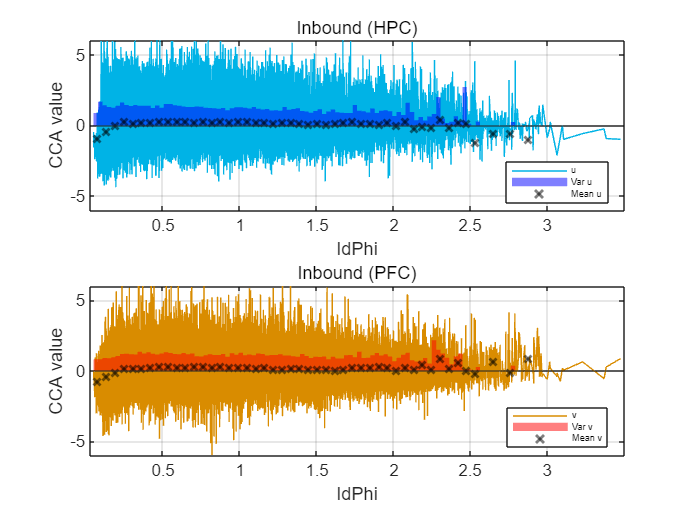




% First plot
subplot(2, 1, 1);

a1 = plot(C_sorted, A_sorted, 'color', [0, 0.7, 0.9, 0.1], 'LineWidth', 0.5);
%scatter(C_sorted, A_sorted, 5, 'Marker', 'o', 'MarkerFaceColor', [0, 0.7, 0.9], 'MarkerFaceAlpha', 0.1);
hold on
yline(0)
hold on
a2 = bar(bin_center, var_u1, 'FaceColor', "b", 'EdgeColor', 'none', 'FaceAlpha', 0.5, "BarWidth", 1);
hold on
a3 = scatter(scatter_center, mean_values_u2, 30, 'Marker', 'x', 'MarkerEdgeColor', "k", 'LineWidth', 1.5);
hold on

xlabel('IdPhi');
ylabel('CCA value');
title('Inbound (HPC)');
grid on;
alpha(0.5);
ylim([-6,6])
legend([a1,a2,a3],{'u',"Var u ",'Mean u'}, 'Location', 'best', "fontsize", 5);

hold off;

% Second plot
subplot(2, 1, 2);
a1 = plot(C_sorted, B_sorted, 'color', [0.85, 0.55, 0, 0.1], 'LineWidth', 0.5);
hold on
yline(0)
hold on;
a2 = bar(bin_center, var_v1, 'FaceColor', "r", 'EdgeColor', 'none', 'FaceAlpha', 0.5, "BarWidth", 1);
hold on
a3 = scatter(scatter_center, mean_values_v2, 30, 'Marker', 'x', 'MarkerEdgeColor', "k", 'LineWidth', 1.5);
hold on

xlabel('IdPhi');
ylabel('CCA value');
title('Inbound (PFC)');
grid on;
legend([a1,a2,a3],{'v', "Var v ",'Mean v'}, 'Location', 'best', "fontsize", 5);
alpha(0.5);  % Set line transparency
hold off;
ylim([-6,6])
saveas(gcf, 'F:/ComSub/Figures/idphi and reward/IdPhi-Neural-Activity-Inbound-dim3.png');

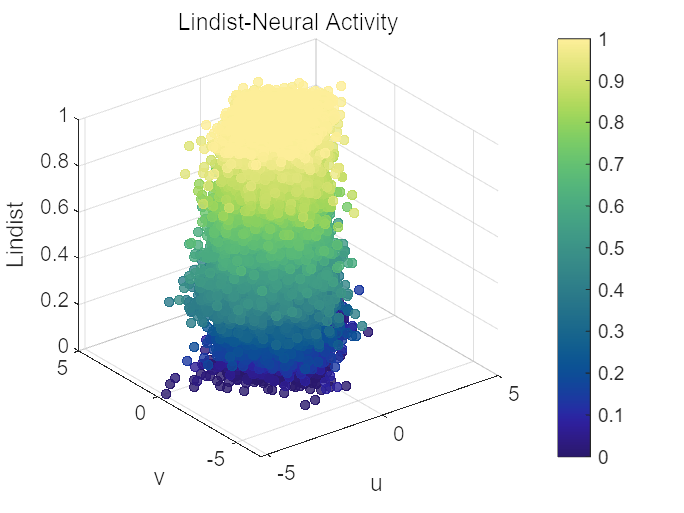

% 假设 A、B、C 分别是你的向量
A = matched_u; % 示例随机数据
B = matched_v; % 示例随机数据
C = lindist; % 示例随机数据

% 使用 scatter3 创建散点图
figure;
scatter3(A, B, C, 20, C, 'filled',"MarkerEdgeColor","flat","MarkerFaceAlpha",0.8);
colormap(cmocean('haline')); % 设置颜色映射为 cmocean 的 'haline' 映射
colorbar; % 添加颜色条
xlabel('u');
ylabel('v');
zlabel('Lindist');
title('Lindist-Neural Activity');

saveas(gcf,"F:/ComSub/Figures/idphi and reward/Lindist-Neural Activity.png")

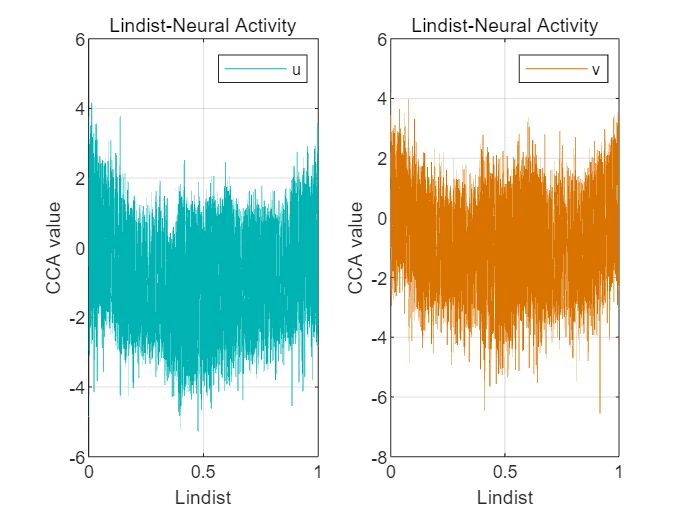

% 对 C 向量进行排序，同时重新排列 A 和 B 向量的元素
[C_sorted, sort_indices] = sort(lindist, 'descend');
A_sorted = matched_u(sort_indices);
B_sorted = matched_v(sort_indices);

figure;

% 调整子图的位置和大小
subplot(1, 2, 1); % [left, bottom, width, height]
plot(C_sorted, A_sorted, 'color', [0, 0.7, 0.7], 'LineWidth', 0.5);
xlabel('Lindist');
ylabel('CCA value');
title('Lindist-Neural Activity');
grid on;
legend('u');

subplot(1, 2, 2);
plot(C_sorted, B_sorted, 'color', [0.85, 0.45, 0], 'LineWidth', 0.5);
xlabel('Lindist');
ylabel('CCA value');
title('Lindist-Neural Activity');
grid on;
legend('v');
saveas(gcf,"F:/ComSub/Figures/idphi and reward/Lindist-Neural Activity2D.png")